## **Fuselage Loads**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

% 0 Design Parameters

% 0.1 Initial constant

g = 9.80665;            % Standard acceleration of gravity (m/s^2)
fuselage_length = 74.4; % Fuselage length (m)

% 0.2 Setup

dx  = 0.1;                             % Spatial discretization step (m）
x_stations = 0 : dx : fuselage_length; % Station array
W_total = zeros(size(x_stations));     % Initialize weight distribution (kg/m)

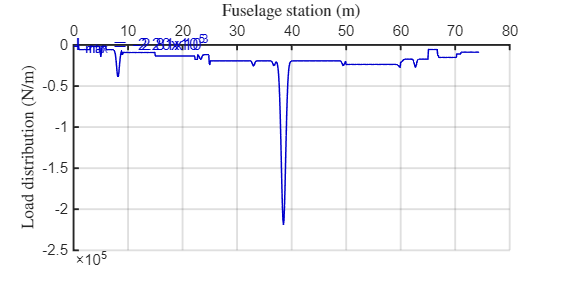

% 1 Weight Distributions

% The inertial load distribution was estimated using assumptions of constant and weighted distributions for each element
% 1.1 Fuselage Shell

fuselage_shell_weight = 11325.39;

idx_full_length = (x_stations >= 0 + dx & x_stations <= fuselage_length);

W_total(idx_full_length) = W_total(idx_full_length) + fuselage_shell_weight / fuselage_length;

% 1.2 Tail Group

tail_weight = 2981.50;

x_tail_start = fuselage_length - 7.63;  
x_tail_end   = fuselage_length;

idx_tail = (x_stations >= x_tail_start & x_stations <= x_tail_end);

if any(idx_tail)

    W_total(idx_tail) = W_total(idx_tail) + tail_weight / (x_tail_end - x_tail_start);

end

% 1.3 Control Surfaces

ctrl_surf_weight = 2688.32;

idx_ctrl = (x_stations >= x_tail_start & x_stations <= x_tail_end);

if any(idx_ctrl)

    W_total(idx_ctrl) = W_total(idx_ctrl) + ctrl_surf_weight / (x_tail_end - x_tail_start);

end

% 1.4 Landing Gear
% Nose + main gear lumps
nose_gear_weight_kg = 2222.22;
main_gear_weight_kg = 20368.68;

nose_gear_sigma = 0.26;
nose_gear_gauss = exp(-0.5*((x_stations - 8.15) ./ nose_gear_sigma).^2);
nose_gear_gauss = nose_gear_gauss / sum(nose_gear_gauss*dx) * nose_gear_weight_kg;
W_total = W_total + nose_gear_gauss;

main_gear_sigma = 0.4;
main_gear_gauss = exp(-0.5*((x_stations - 38.5) ./ main_gear_sigma).^2);
main_gear_gauss = main_gear_gauss / sum(main_gear_gauss*dx) * main_gear_weight_kg;
W_total = W_total + main_gear_gauss;

% 1.5 Electrical System
% Forward bay + small aft lump

electrical_weight_kg = 690.75;

x_elec_start = 6; x_elec_end = 9;

idx_elec = (x_stations >= x_elec_start & x_stations <= x_elec_end);

if any(idx_elec)

    W_total(idx_elec) = W_total(idx_elec) + electrical_weight_kg/(x_elec_end - x_elec_start);

end

% Aft electronics near x=60 (Gaussian)
aft_elec_weight_kg = 300;

sigma_aft_elec = 0.3;

aft_elec_gauss = exp(-0.5*((x_stations - 60) ./ sigma_aft_elec).^2);

aft_elec_gauss = aft_elec_gauss / sum(aft_elec_gauss*dx) * aft_elec_weight_kg;

W_total = W_total + aft_elec_gauss;

% 1.6 Hydraulic System

hydraulic_weight_total_kg = 920.23;
hyd_reservoir_lump = 1227.84 - hydraulic_weight_total_kg; 
hyd_lines_weight   = hydraulic_weight_total_kg - hyd_reservoir_lump;

% Reservoir near x=33 (Gaussian)

x_hyd_center = 33; 
sigma_hyd    = 0.2;

hyd_center_gauss = exp(-0.5*((x_stations - x_hyd_center)./sigma_hyd).^2);
hyd_center_gauss = hyd_center_gauss / sum(hyd_center_gauss*dx) * hyd_reservoir_lump;

W_total = W_total + hyd_center_gauss;

% Lines uniform from x=10 to x=60

idx_hyd_lines = (x_stations >= 10 & x_stations <= 60);

if any(idx_hyd_lines)

    W_total(idx_hyd_lines) = W_total(idx_hyd_lines) + (hyd_lines_weight / (60 - 10));

end

% 1.7 Cabin Furnishings & Seating

n_first_class  = 0;
n_business     = 70; 
n_economy      = 430;
seat_wt_first  = 25; 
seat_wt_bus    = 22; 
seat_wt_eco    = 15; 
avg_passenger_kg = 42670.04 / 516;

% First Class: x=6–12
W_first_total = n_first_class * (seat_wt_first + avg_passenger_kg);
idx_first = (x_stations >= 6 & x_stations <= 12);

if any(idx_first)

    W_total(idx_first) = W_total(idx_first) + W_first_total / (12 - 6);

end

% Business Class: x=12–25
W_bus_total = n_business * (seat_wt_bus + avg_passenger_kg);
idx_bus = (x_stations >= 7.8+1.07 & x_stations <= 7.8+1.07+13.93);

if any(idx_bus)

    W_total(idx_bus) = W_total(idx_bus) + W_bus_total / (25 - 12);

end

% Economy Class: x=25–650
W_eco_total = n_economy * (seat_wt_eco + avg_passenger_kg);
idx_eco = (x_stations >= 24.9 & x_stations <= 65);

if any(idx_eco)

    W_total(idx_eco) = W_total(idx_eco) + W_eco_total / (60 - 25);

end

% Overhead bins, monuments, etc.
furnishings_weight_kg = 8561.36 + 1610;
idx_furnish = (x_stations >= 6 & x_stations <= 60);

if any(idx_furnish)

    W_total(idx_furnish) = W_total(idx_furnish) + furnishings_weight_kg / (60 - 6);

end

% 1.8 Lavatories + Galleys 
% Lumps

lav_galley_locs   = 7.8 + [1.07+13.93+0.5, ...
                           1.07+13.93+2.1+11.36+0.5, ...
                           1.07+13.93+2.1+11.36+2.1+10.62+0.5, ...
                           1.07+13.93+2.1+11.36+2.1+10.62+2.1+10.62+1];

lav_galley_wt_kg  = [300, 300, 300, 500];

for i = 1:length(lav_galley_locs)

    sigma_lav = 0.2;
    gauss_lav = exp(-0.5*((x_stations - lav_galley_locs(i)) ./ sigma_lav).^2);
    gauss_lav = gauss_lav / sum(gauss_lav*dx) * lav_galley_wt_kg(i);
    W_total = W_total + gauss_lav;

end

% 1.9 Cargo 
% Forward hold x=15–25, aft hold x=50–60

cargo_fwd_weight_kg = 8717.6 * 0.5;
cargo_aft_weight_kg = 8717.6 * 0.5;

idx_cargo_fwd = (x_stations >= 15 & x_stations <= 25);

if any(idx_cargo_fwd)

    W_total(idx_cargo_fwd) = W_total(idx_cargo_fwd) + cargo_fwd_weight_kg / (25 - 15);

end

idx_cargo_aft = (x_stations >= 50 & x_stations <= 60);

if any(idx_cargo_aft)

    W_total(idx_cargo_aft) = W_total(idx_cargo_aft) + cargo_aft_weight_kg / (60 - 50);

end

% 1.10 Flight Crew

pilot_wt_kg   = avg_passenger_kg;  
num_pilots    = 4;
cabin_crew_wt_kg = avg_passenger_kg; 
num_cabin_crew    = 12;

% Pilots near x=5 (small Gaussian)
pilot_sigma = 0.1;
pilot_gauss = exp(-0.5*((x_stations - 5)./pilot_sigma).^2);
pilot_gauss = pilot_gauss / sum(pilot_gauss*dx) * (pilot_wt_kg*num_pilots);
W_total = W_total + pilot_gauss;

% Cabin crew distributed from x=6 to x=60
crew_weight_total = cabin_crew_wt_kg * num_cabin_crew;
idx_crew = (x_stations >= 6 & x_stations <= 60);

if any(idx_crew)

    W_total(idx_crew) = W_total(idx_crew) + crew_weight_total / (60 - 6);

end

% 1.11 APU
% In tail region
apu_weight_kg = 935;

x_apu_start = 67; x_apu_end = 71;

idx_apu = (x_stations >= x_apu_start & x_stations <= x_apu_end);

if any(idx_apu)

    W_total(idx_apu) = W_total(idx_apu) + apu_weight_kg / (x_apu_end - x_apu_start);

end

% 1.12 Air Conditioning
% x=22.3–70.2
aircond_wt_kg = 19439.11;

x_ac_start = 22.3; x_ac_end = 70.2;

idx_ac = (x_stations >= x_ac_start & x_stations <= x_ac_end);

if any(idx_ac)

    W_total(idx_ac) = W_total(idx_ac) + aircond_wt_kg / (x_ac_end - x_ac_start);

end

% 1.13 Anti-Icing
% near nose x=1–3

anti_icing_weight_kg = 859.8;

x_anti_start = 1; x_anti_end = 3;

idx_anti = (x_stations >= x_anti_start & x_stations <= x_anti_end);

if any(idx_anti)

    W_total(idx_anti) = W_total(idx_anti) + anti_icing_weight_kg / (x_anti_end - x_anti_start);

end

% 1.14 Plot load distributions
figure(1)

clf;

plot(x_stations, -W_total*g, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

txt1 = 'L_{max} = -2.81x10^3';
txt2 = 'L_{min} = -2.20x10^5';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Load distribution (N/m)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);

**1.15 Basic Check**

Check weight & CG position

W_total_kg = sum(W_total)*dx;
CG_total_m = sum(x_stations .* W_total)*dx / W_total_kg;
disp(['Total Mass = ', num2str(W_total_kg,'%8.1f'),' kg']);

Total Mass = 140654.2 kg


disp(['Fuselage Station CG = ', num2str(CG_total_m,'%4.2f'),' m']);

Fuselage Station CG = 40.57 m


W_total_N = W_total_kg * g

W_total_N = 1.3793e+06

W_total_N * 3.75

ans = 5.1725e+06

### **2 Inertia Load**

Suppose we treat the fuselage as a beam supported at two points:

x_sparFront, x_sparRear

We find R_sparFront_kg, R_sparRear_kg so that sum of forces & moments = 0.

% Moment about x=0 (nose):
M_nose_kgm = sum(W_total .* x_stations)*dx;  % in (kg·m), if w_total is (kg/m)

% Example front & rear spar locations
LE = 26.5;
TE = 39.5;

x_sparFront = (LE + (TE-LE) * 0.2);  % old "Rf_loc"
x_sparRear  = (LE + (TE-LE) * 0.7);  % old "Rr_loc"

1) R_sparFront + R_sparRear = W_total_kg

2) x_sparFront*R_sparFront + x_sparRear*R_sparRear = M_nose_kgm

% Matrix form => [ -x_sparRear, -x_sparFront; -1, -1 ] * [R_rear; R_front] = [ -M; -W ]
A_spars = [-x_sparRear, -x_sparFront; -1 , -1];
b_spars = [-M_nose_kgm; -W_total_kg];

reactions_spar = A_spars \ b_spars; 

% [R_sparRear_kg; R_sparFront_kg] 
R_sparRear_kg  = reactions_spar(1);
R_sparFront_kg = reactions_spar(2);

disp('--- Spar Reaction Forces (mass, kg) about x=0 ---');

--- Spar Reaction Forces (mass, kg) about x=0 ---


disp(['R_sparRear_kg  = ', num2str(R_sparRear_kg,'%8.2f')]);

R_sparRear_kg  = 248121.02


disp(['R_sparFront_kg = ', num2str(R_sparFront_kg,'%8.2f')]);

R_sparFront_kg = -107466.84


R_sparFront_N = R_sparFront_kg * g

R_sparFront_N = -1.0539e+06

R_sparRear_N = R_sparRear_kg * g

R_sparRear_N = 2.4332e+06

### **3 Air Load**

Tailplane load T_tail_N acts at x_tail. 

Sum of forces: R_sparFront_N + R_sparRear_N + T_tail_N = 0

Sum of moments about x=0: R_sparFront_N*x_sparFront + R_sparRear_N*x_sparRear + T_tail_N*x_tail = 0

x_tail   = 72.2;    % (m)
T_tail_N = -54351;  % negative => downward

% Solve similarly:
% R_sparRear_N = -T_tail_N - R_sparFront_N, etc.

% For brevity, let's just show a solution form:
R_sparFront_N_tail = - T_tail_N * ((x_tail - x_sparRear)/(x_sparFront - x_sparRear));
R_sparRear_N_tail  = - T_tail_N - R_sparFront_N_tail;

disp('--- Tailplane Load Reactions on Two Spars ---');

--- Tailplane Load Reactions on Two Spars ---


disp(['Tail load = ', num2str(T_tail_N),' N (negative => downward)']);

Tail load = -54351 N (negative => downward)


disp(['R_sparFront_N = ', num2str(R_sparFront_N_tail,'%8.2f'),' N']);

R_sparFront_N = -306037.94 N


disp(['R_sparRear_N  = ', num2str(R_sparRear_N_tail,'%8.2f'),' N']);

R_sparRear_N  = 360388.94 N


### A Symetric Loading

**A1 Positive Ultimate Load**

n = 3.75

R_sparFront_n1 = R_sparFront_N * 3.75

R_sparFront_n1 = -3.9521e+06

R_sparRear_n1 = R_sparRear_N * 3.75

R_sparRear_n1 = 9.1246e+06

W_total_n1 = W_total .* 3.75 .* g

W_total_n1 = 1.0e+05 *

    0.0000    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.2141    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0560    0.0561    0.0614    0.1217    0.3503


sum(W_total_n1) * dx

ans = 5.1725e+06

R_sparFront_n2 = R_sparFront_N_tail * 3.75

R_sparFront_n2 = -1.1476e+06

R_sparRear_n2 = R_sparRear_N_tail * 3.75

R_sparRear_n2 = 1.3515e+06

T_tail_n2 = T_tail_N * 3.75

T_tail_n2 = -2.0382e+05

**A2 Negative Ultimate Load**

n = -1.5

R_sparFront_neg1 = R_sparFront_N * -1.5

R_sparFront_neg1 = 1.5808e+06

R_sparRear_neg1 = R_sparRear_N * -1.5

R_sparRear_neg1 = -3.6499e+06

W_total_neg1 = W_total .* -1.5 .* g

W_total_neg1 = 1.0e+05 *

   -0.0000   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0856   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0224   -0.0225   -0.0245   -0.0487   -0.1401


sum(W_total_neg1) * dx

ans = -2.0690e+06

R_sparFront_neg2 = R_sparFront_N_tail * -1.5

R_sparFront_neg2 = 4.5906e+05

R_sparRear_neg2 = R_sparRear_N_tail * -1.5

R_sparRear_neg2 = -5.4058e+05

T_tail_neg2 = T_tail_N * -1.5

T_tail_neg2 = 8.1526e+04

### B Nose-gear-off Landing

n = 2.8199

% Example load factor for on-ground (or maneuver)
n_land = 2.8199;  

% Total aircraft weight (N) under load factor
W_total_land = W_total_N * n_land

W_total_land = 3.8896e+06

% Example tail load (N); negative => downward
T_tail_N = 0  % placeholder (downward 20,000 N, for example)

T_tail_N = 0

% Since only main gear carries the load:
% Sum of vertical forces = 0  =>  R_main + (T_tail) + (-W_total) = 0
% =>  R_main = W_total - T_tail
% (Here, W_total is positive downward, T_tail negative => also downward,
% so R_main must be upward = W_total - (negative) => W_total + |T_tail| )

R_mainGear = W_total_land - T_tail_N

R_mainGear = 3.8896e+06

W_total_land = W_total .* n_land .* g

W_total_land = 1.0e+05 *

    0.0000    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.1610    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0421    0.0422    0.0461    0.0915    0.2634


sum(W_total_land) * dx

ans = 3.8896e+06

### **C OEI**

Fmax = 286.6e3;
engine1 = 0.27;
engine2 = 0.62;
b = 65;
ye = b/2*engine2;

xle = 26.5;
xac = xle + 10.1;
xe = 31.3;
xvtac = xac + 30.7;
dx_e = xvtac - xe;

Fy = Fmax*ye/dx_e

Fy = 1.6042e+05

### D Stored value

Sym = zeros(7, length(x_stations));
Sym(1, :) = x_stations;
Sym(2, :) = W_total_n1 .* dx;
Sym(2, end) = Sym(2, end) + Sym(2, 1);
Sym(2, 1) = 0;
Sym(3, 292) = R_sparFront_n1;
Sym(4, 357) = R_sparRear_n1;
Sym(5, 292) = R_sparFront_n2;
Sym(6, 357) = R_sparRear_n2;
Sym(7, 723) = T_tail_n2;


Sym_neg = zeros(7, length(x_stations));
Sym_neg(1, :) = x_stations;
Sym_neg(2, :) = W_total_neg1 .* dx;
Sym_neg(2, end) = Sym_neg(2, end) + Sym_neg(2, 1);
Sym_neg(2, 1) = 0;
Sym_neg(3, 292) = R_sparFront_neg1;
Sym_neg(4, 357) = R_sparRear_neg1;
Sym_neg(5, 292) = R_sparFront_neg2;
Sym_neg(6, 357) = R_sparRear_neg2;
Sym_neg(7, 723) = T_tail_neg2;

Landing = zeros(3, length(x_stations));
Landing(1, :) = x_stations;
Landing(2, :) = W_total_land .* dx;
Landing(2, end) = Landing(2, end) + Landing(2, 1);
Landing(2, 1) = 0;
Landing(3, 357) = R_mainGear;

OEI = zeros(2, length(x_stations));
OEI(1, :) = x_stations;
OEI(2, 674) = Fy;

save('Case.mat', 'Sym', 'Sym_neg', 'Landing', 'OEI')